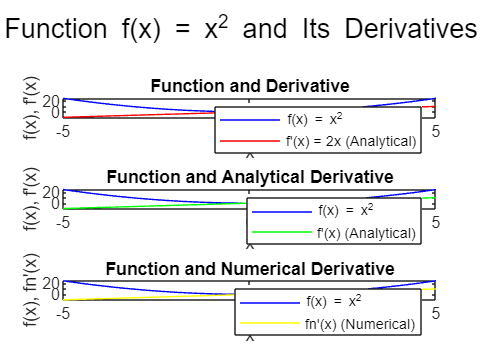

% Define the function and its derivative
f = @(x) x.^2;  % Original function
df = @(x) 2*x;  % derivative

% Define the range of x values
x_values = -5:0.1:5;

% Calculate the numerical derivative using finite differences
h = 1e-6;  % Small step size
df_analytical = (f(x_values + h) - f(x_values)) / h;

n = 1000000;
df_numerical = (f(x_values + (1/n)) - f(x_values)) / (1/n);

% Plot the original function, analytical derivative, and numerical derivative
figure;
subplot(3,1,1);
plot(x_values, f(x_values), 'b', x_values, df(x_values), 'r');
xlabel('x');
ylabel('f(x), f''(x)');
legend('f(x) = x^2', "f'(x) = 2x (Analytical)");
title("Function and Derivative");

subplot(3,1,2);
plot(x_values, f(x_values), 'b', x_values, df_analytical, 'g');
xlabel('x');
ylabel('f(x), f''(x)');
legend('f(x) = x^2', "f'(x) (Analytical)");
title("Function and Analytical Derivative");

subplot(3,1,3);
plot(x_values, f(x_values), 'b', x_values, df_numerical, 'y');
xlabel('x');
ylabel('f(x), fn''(x)');
legend('f(x) = x^2', "fn'(x) (Numerical)");
title("Function and Numerical Derivative");

sgtitle("Function f(x) = x^2 and Its Derivatives");

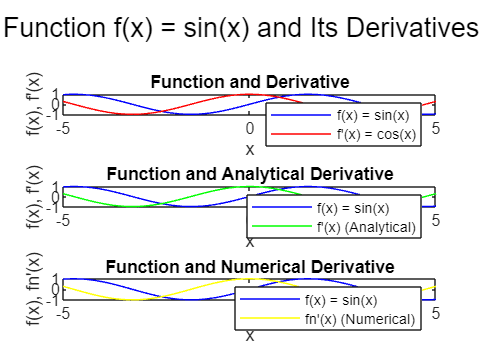

% Define the function and its derivative
f_sin = @(x) sin(x);  % Original function
df_analytical_sin = @(x) cos(x);  % Analytical derivative

% Calculate the numerical derivative using finite differences
df_numerical_sin = (f_sin(x_values + h) - f_sin(x_values)) / h;

n = 1000000;
df_sin = (f_sin(x_values + 1/n) - f_sin(x_values)) / (1/n);

% Plot the original function, analytical derivative, and numerical derivative
figure;
subplot(3,1,1);
plot(x_values, f_sin(x_values), 'b', x_values, df_analytical_sin(x_values), 'r');
xlabel('x');
ylabel('f(x), f''(x)');
legend('f(x) = sin(x)', "f'(x) = cos(x)");
title("Function and Derivative");

subplot(3,1,2);
plot(x_values, f_sin(x_values), 'b', x_values, df_numerical_sin, 'g');
xlabel('x');
ylabel('f(x), f''(x)');
legend('f(x) = sin(x)', "f'(x) (Analytical)");
title("Function and Analytical Derivative");

subplot(3,1,3);
plot(x_values, f_sin(x_values), 'b', x_values, df_sin, 'y' )
xlabel('x');
ylabel('f(x), fn''(x)');
legend('f(x) = sin(x)', "fn'(x) (Numerical)");
title("Function and Numerical Derivative");

sgtitle("Function f(x) = sin(x) and Its Derivatives");